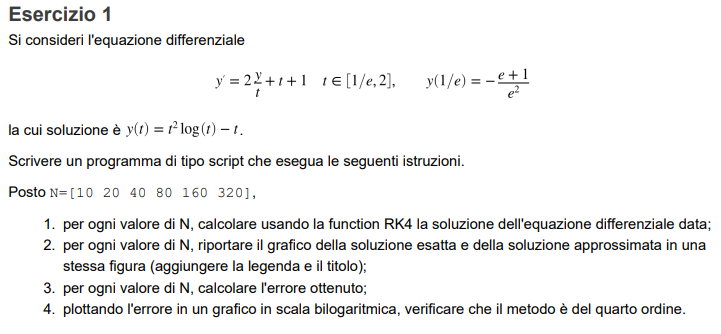

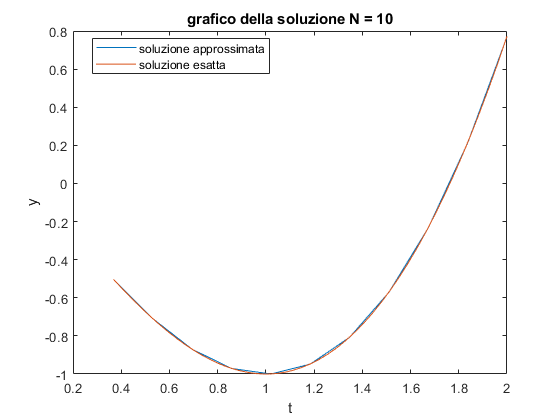

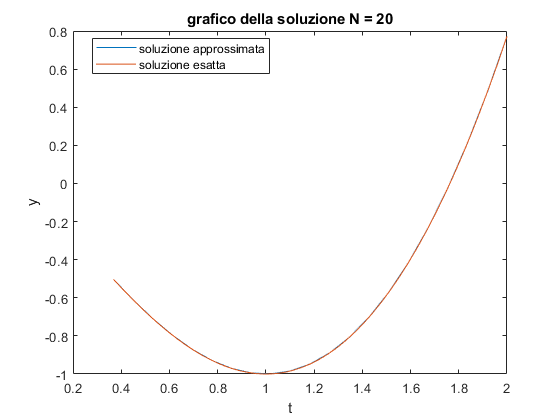

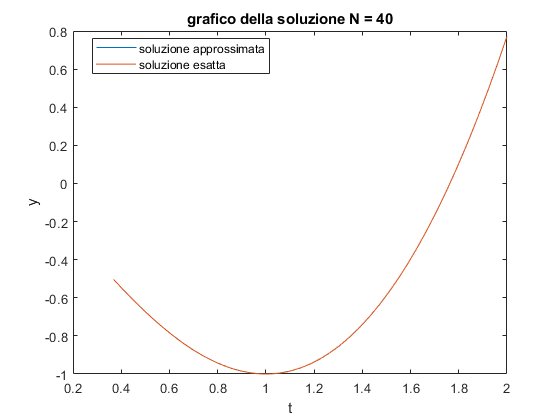

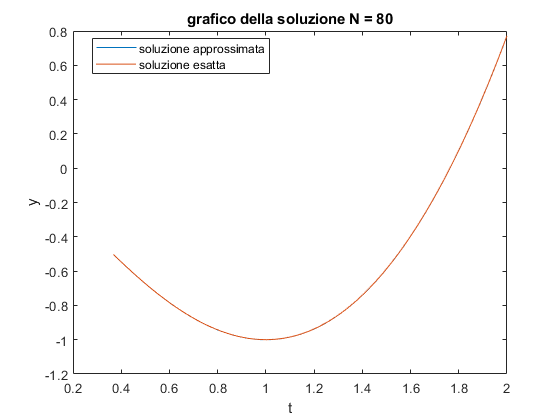

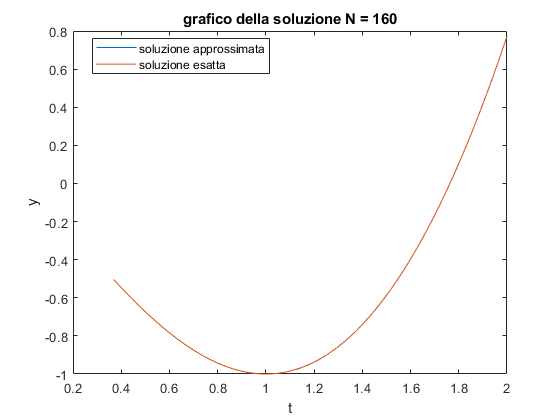

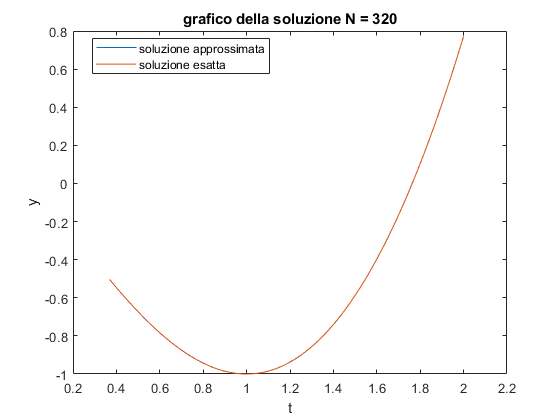

clear all
close all
N = [10 20 40 80 160 320];

f = @(t,y) 2.*y./t+t+1;

ys = @(t) t.^2.*log(t)-t;
e = exp(1);
err = zeros(1,length(N));
y0 = -(e+1)/(e^2);
h = zeros(1,length(N));
for i = 1:1:length(N)
    [tt,u,h(i)]=RK4(f,1/e,2,y0,N(i));
    figure
    plot(tt,u)
    hold on 
    fplot(ys,[1/e 2])
    title("grafico della soluzione N = " +N(i))
    xlabel t
    ylabel y
    legend("soluzione approssimata","soluzione esatta","Location","best")
    err(i) =max(abs(u-ys(tt)));
    %err(i) = norm(u-ys(tt),inf);
end

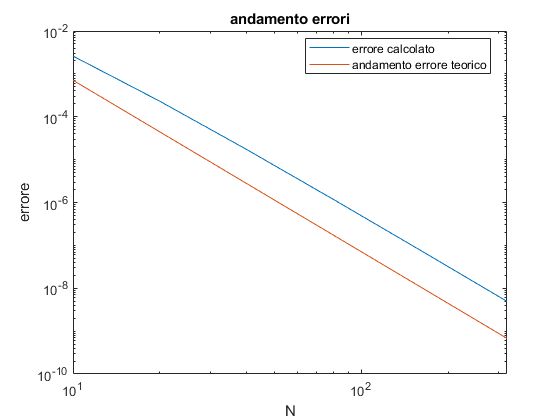

figure
loglog(N,err,N,h.^4)
xlabel N
ylabel errore
title("andamento errori")
legend("errore calcolato","andamento errore teorico","Location","best")

disp("il metodo è verificato essere del 4° ordine dato che l'errore ha l'andamenot di h^4")

il metodo è verificato essere del 4° ordine dato che l'errore ha l'andamenot di h^4


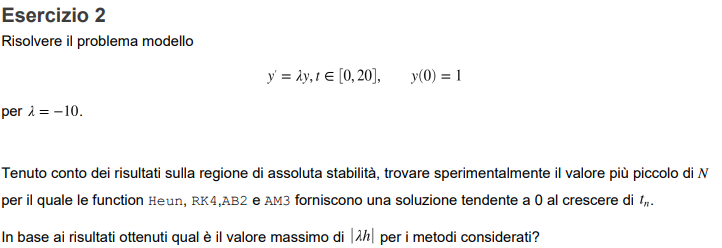

clear all
close all
lambda = -10;
f1 = @(t,y) lambda*y;
t0 = 0;
T = 20;
y0 = 1;
LH=[];

LH =
     []


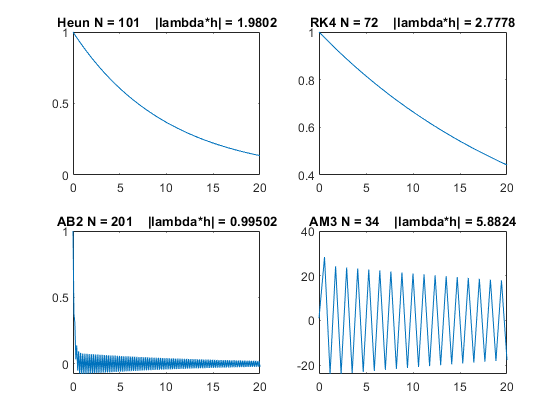

% for n = 30:10:210
%     t=[];u=[];
%     LH=[LH abs(lambda*(T-t0)/n)];
%     [t(1,:),u(1,:)]=Heun(f1,t0,T,y0,n);%100/110
%     [t(2,:),u(2,:)]=RK4(f1,t0,T,y0,n);%70/80
%     [t(3,:),u(3,:)]=AB2(f1,t0,T,y0,n);%190/200
%     [t(4,:),u(4,:)]=AM3(f1,t0,T,y0,n);%30/40
%     figure
%     for i=1:4
%         subplot(2,2,i)
%         plot(t(i,:),u(i,:))
%         title(n)
%     end
% end
[t1,u1]=Heun(f1,t0,T,y0,101);
[t2,u2]=RK4(f1,t0,T,y0,72);
[t3,u3]=AB2(f1,t0,T,y0,201);
[t4,u4]=AM3(f1,t0,T,y0,34);

for i=1:4
         subplot(2,2,i)
         
         switch i
             case 1 
                 lh = abs(lambda*(T-t0)/101);
                 n ="Heun N = 101    |lambda*h| = " + lh;
                 plot(t1,u1)
             case 2
                 lh = abs(lambda*(T-t0)/72);
                 n ="RK4 N = 72    |lambda*h| = " + lh;
                 plot(t2,u2)
             case 3
                 lh = abs(lambda*(T-t0)/201);
                 n ="AB2 N = 201    |lambda*h| = " + lh;
                 plot(t3,u3)
             case 4
                 lh = abs(lambda*(T-t0)/34);
                 n ="AM3 N = 34    |lambda*h| = " + lh;
                 plot(t4,u4)
         end
         title(n)
end

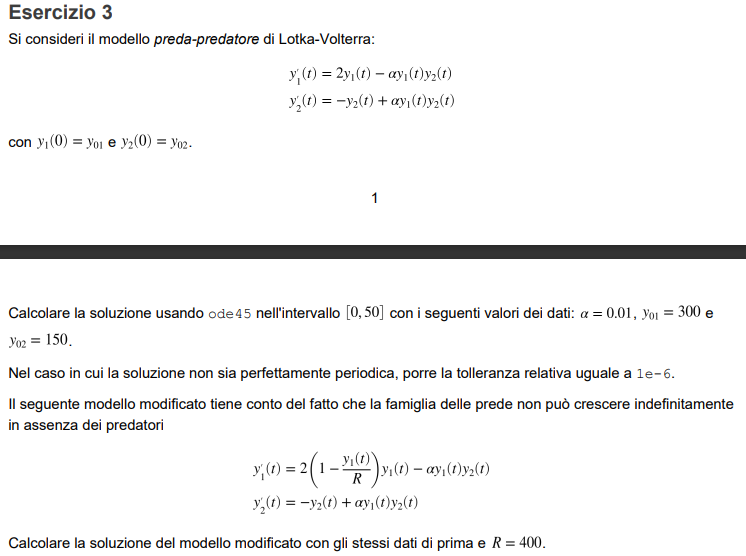

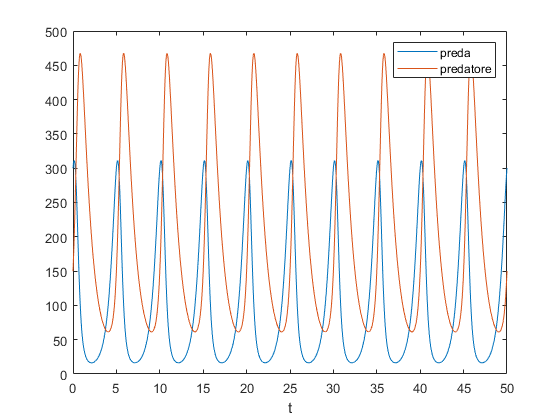

clear all
close all
y0 = [300 150];
alpha = 0.01;
opt =odeset("RelTol",1e-6);
f =@(t,y) [2*y(1)-alpha*y(1).*y(2); -y(2)+alpha*y(1).*y(2)];
[t,u] = ode45(f,[0 50],y0,opt);
plot(t,u)
legend("preda","predatore")
xlabel t

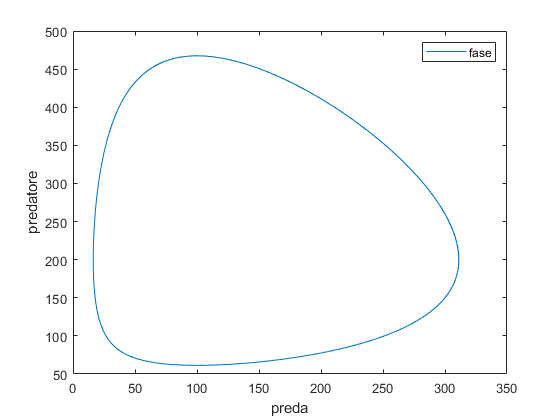

plot(u(:,1),u(:,2))
legend("fase")
xlabel preda
ylabel predatore

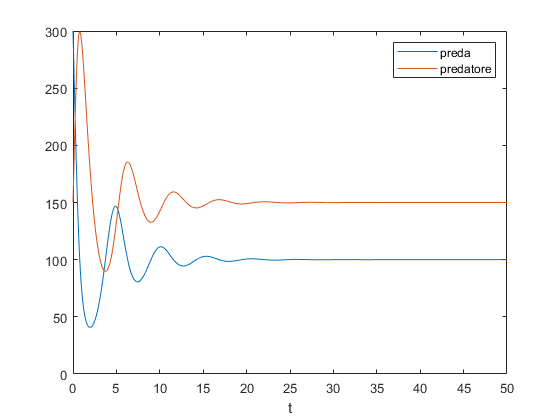


R =400;
f =@(t,y) [2*(1-y(1)./R).*y(1)-alpha*y(1).*y(2); -y(2)+alpha*y(1).*y(2)];
[t,u] = ode45(f,[0 50],y0,opt);
plot(t,u)
legend("preda","predatore")
xlabel t

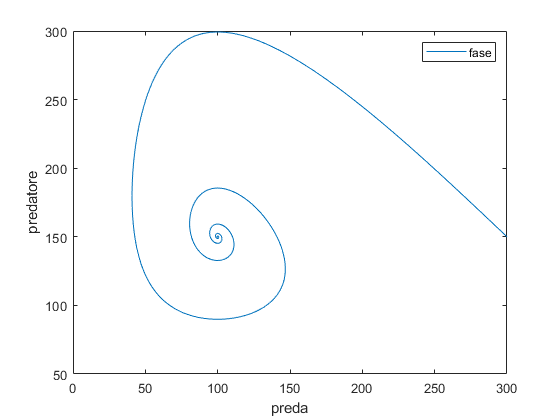

plot(u(:,1),u(:,2))
legend("fase")
xlabel preda
ylabel predatore